clc;
clear;

syms C_filt R_Filt R_in C_par R_on C_sample positive;

syms s;

syms v_i v_1 v_2 v_o;

eq1 = (v_1 - v_i)/R_Filt + v_1*s*C_filt + (v_1 - v_2)/R_in == 0

$$eq1 = \frac{v_{1}-v_{2}}{R_{\mathrm{in}}}+\frac{v_{1}-v_{i}}{R_{\mathrm{Filt}}}+C_{\mathrm{filt}}\,s\,v_{1}=0$$

eq2 = (v_2 - v_1)/R_in + + v_2*s*C_par + (v_2 - v_o)/R_on == 0

$$eq2 = \frac{v_{2}-v_{o}}{R_{\mathrm{on}}}-\frac{v_{1}-v_{2}}{R_{\mathrm{in}}}+C_{\mathrm{par}}\,s\,v_{2}=0$$

eq3 = (v_o - v_2)/R_on + v_o*s*C_sample == 0

$$eq3 = C_{\mathrm{sample}}\,s\,v_{o}-\frac{v_{2}-v_{o}}{R_{\mathrm{on}}}=0$$

sol = solve(eq1, eq2, eq3, v_1, v_2, v_o);

simplify(sol.v_o)

$$ans = \frac{v_{i}}{C_{\mathrm{filt}}\,R_{\mathrm{Filt}}\,s+C_{\mathrm{par}}\,R_{\mathrm{Filt}}\,s+C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,s+C_{\mathrm{par}}\,R_{\mathrm{in}}\,s+C_{\mathrm{sample}}\,R_{\mathrm{in}}\,s+C_{\mathrm{sample}}\,R_{\mathrm{on}}\,s+C_{\mathrm{filt}}\,C_{\mathrm{par}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,s^{2}+C_{\mathrm{filt}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,s^{2}+C_{\mathrm{filt}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{on}}\,s^{2}+C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{on}}\,s^{2}+C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{in}}\,R_{\mathrm{on}}\,s^{2}+C_{\mathrm{filt}}\,C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,R_{\mathrm{on}}\,s^{3}+1}$$


% when switch closed
simplify(limit(sol.v_o, R_on, inf))

$$ans = 0$$

[n,d] = numden(sol.v_o);
simplify(d)

$$ans = C_{\mathrm{filt}}\,R_{\mathrm{Filt}}\,s+C_{\mathrm{par}}\,R_{\mathrm{Filt}}\,s+C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,s+C_{\mathrm{par}}\,R_{\mathrm{in}}\,s+C_{\mathrm{sample}}\,R_{\mathrm{in}}\,s+C_{\mathrm{sample}}\,R_{\mathrm{on}}\,s+C_{\mathrm{filt}}\,C_{\mathrm{par}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,s^{2}+C_{\mathrm{filt}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,s^{2}+C_{\mathrm{filt}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{on}}\,s^{2}+C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{on}}\,s^{2}+C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{in}}\,R_{\mathrm{on}}\,s^{2}+C_{\mathrm{filt}}\,C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,R_{\mathrm{on}}\,s^{3}+1$$


collect(d, s)

$$ans = \left(C_{\mathrm{filt}}\,C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}\,R_{\mathrm{on}}\right)\,s^{3}+\left(C_{\mathrm{filt}}\,C_{\mathrm{par}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}+C_{\mathrm{filt}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{in}}+C_{\mathrm{filt}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{on}}+C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{Filt}}\,R_{\mathrm{on}}+C_{\mathrm{par}}\,C_{\mathrm{sample}}\,R_{\mathrm{in}}\,R_{\mathrm{on}}\right)\,s^{2}+\left(C_{\mathrm{filt}}\,R_{\mathrm{Filt}}+C_{\mathrm{par}}\,R_{\mathrm{Filt}}+C_{\mathrm{sample}}\,R_{\mathrm{Filt}}+C_{\mathrm{par}}\,R_{\mathrm{in}}+C_{\mathrm{sample}}\,R_{\mathrm{in}}+C_{\mathrm{sample}}\,R_{\mathrm{on}}\right)\,s+1$$

% Differential equation equivalent

% --- parameters (you can adjust these) ---
R_Filt   = 24.9;    % Ω
R_in     = 10;      % Ω
R_on     = 28;      % Ω
C_filt   = 3e-9;    % F
C_par    =  2e-12;  % F
C_sample = 18e-12;  % F

% pack into a struct for easy passing
p.RF = R_Filt;
p.Ri = R_in;
p.Ro = R_on;
p.Cf = C_filt;
p.Cp = C_par;
p.Cs = C_sample;

C_array = linspace(82e-12, 5e-9, 100);

% define the target
v_target = 1 - 2^(-19);

% First sample

out_f = zeros(size(C_array));

% initial conditions
v1_0 = 0;  % V
v2_0 = 0;  % V
vo_0 = 0;  % V

% time span
tspan = [0 2e-6];  % e.g. 0 to 200 ns

opts = odeset( ...
  'RelTol',1e-9, ...           % relative tolerance
  'AbsTol',1e-12, ...          % absolute tolerance
  'MaxStep',1e-10 ...          % maximum step size of 0.1 ns
);

for k = 1:length(C_array)
    p.Cf = C_array(k);

    % call ode45
    [t, x] = ode45(@(t,x) odefun(t,x,p), tspan, [v1_0; v2_0; vo_0], opts);

    % maximum frequency.
    out_f(k) = 1/(t(find( x(:,3) >= v_target, 1, 'first' )) + 39e-9);
end

% Second sample

out_s = zeros(size(C_array));

% initial conditions
v1_0 = 1;  % V
v2_0 = 1;  % V
vo_0 = 0;  % V

for k = 1:length(C_array)

    p.Cf = C_array(k);

    % call ode45
    [t, x] = ode45(@(t,x) odefun(t,x,p), tspan, [v1_0; v2_0; vo_0], opts);

    % maximum frequency.
    out_s(k) = 1/(t(find( x(:,3) >= v_target, 1, 'first' )) + 39e-9);

end

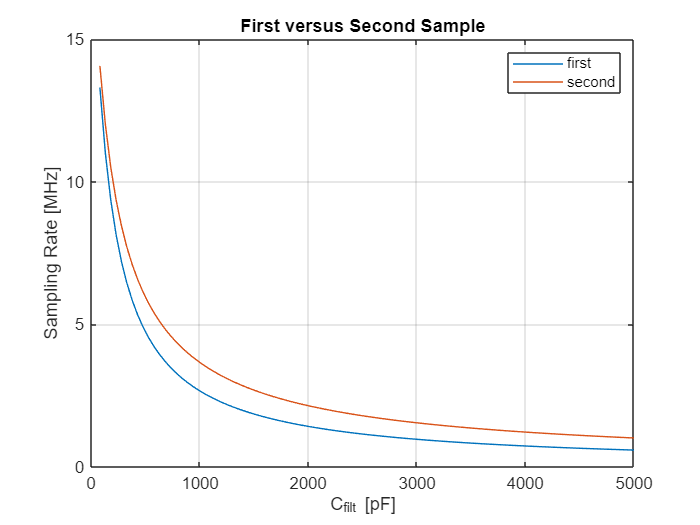

plot(C_array*1e12, out_f/1e6, C_array*1e12, out_s/1e6); grid; title('First versus Second Sample');
xlabel('C_{filt} [pF]'); ylabel('Sampling Rate [MHz]')
legend('first', 'second')

% Now we find for 10 MHz

% initial conditions
v1_0 = 0;  % V
v2_0 = 0;  % V
vo_0 = 0;  % V

p.Cf = 160e-12;

% call ode45
[t, x] = ode45(@(t,x) odefun(t,x,p), tspan, [v1_0; v2_0; vo_0], opts);

% maximum frequency.
1/(t(find( x(:,3) >= v_target, 1, 'first' )) + 39e-9)

ans = 1.0019e+07

% For 10 MHz sampling

C_array(find( out_f <= 10e6, 1, 'first' ))

ans = 1.8135e-10


% --- ODE function ---
function dxdt = odefun(~, x, p)
  v1 = x(1);
  v2 = x(2);
  vo = x(3);

  % dv1/dt from: (v1-1)/RF + Cf*dv1 + (v1-v2)/Ri = 0
  dv1 = ( -(v1-1)/p.RF - (v1-v2)/p.Ri ) / p.Cf;

  % dv2/dt from: (v2-v1)/Ri + Cp*dv2 + (v2-vo)/Ro = 0
  dv2 = ( -(v2-v1)/p.Ri - (v2-vo)/p.Ro ) / p.Cp;

  % dvo/dt from: (vo-v2)/Ro + Cs*dvo = 0
  dv3 = -(vo-v2) / (p.Ro * p.Cs);

  dxdt = [dv1; dv2; dv3];
end